# Macro III: Problem Set 2

Deadline: Wednesday, 29/8/2018

Aluno: Bruno Tebaldi de Queiroz Barbosa (C174887)

Professor: Tiago Cavalcanti

Source code disponível em: [https://github.com/btebaldi/Macro3/tree/master/PSet_02](https://github.com/btebaldi/Macro3/tree/master/PSet_02)

## Stochastic Processes

**(a) Explain the procedures to approximate an AR(1) process**


$$y_t = \mu(1-\rho)+\rho y_{t-1} + \epsilon_t$$


**where **$\epsilon_t \sim N(0,\sigma^2)$**with a Markov chain, based on the Tauchen method (with equal intervals).**

Vamos calcular a variancia e experanca de uma AR(1). Assumindo que $|\rho| \le 1$temos:


$$y_t =\mu(1-\rho) +\rho y_{t-1} + \epsilon_t \\
y_t =\mu(1-\rho) +\rho [\mu(1-\rho) +\rho y_{t-2} + \epsilon_{t-1}] + \epsilon_t \\
y_t =\mu(1-\rho) +\rho [\mu(1-\rho) +\rho [\mu(1-\rho) +\rho y_{t-2} + \epsilon_{t-2}] + \epsilon_{t-1}] + \epsilon_t \\

y_t =\sum_{i=0}^{2}{\rho^i \mu(1-\rho) } +\rho^3 y_{t-2} + \sum_{i=0}^{2}{ \rho^i \epsilon_{t-i}}$$



$$y_t =\sum_{i=0}^{n}{\rho^i \mu(1-\rho) } +\rho^{n+1} y_{t-n} + \sum_{i=0}^{n}{ \rho^i \epsilon_{t-i}}$$



$$\underset{n \rightarrow \infty}{lim} y_t =\sum_{i=0}^{\infty}{\rho^i \mu(1-\rho) } +\rho^{\infty} y_{t-\infty} + \sum_{i=0}^{\infty}{ \rho^i \epsilon_{t-i}} \\

y_t =\frac{\mu(1-\rho)}{1-\rho} + \sum_{i=0}^{\infty}{ \rho^i \epsilon_{t-i}}$$



$$\mathbb{E}[y_t] =\frac{\mu(1-\rho)}{1-\rho} = \mu \\
\mathbb{V}[y_t] = \sum_{i=0}^{\infty}{ \rho^i \mathbb{V}[\epsilon_{t-i}]} = \frac{\sigma^2}{1-\rho} \\
\mathbb{E}[(y_t-\mathbb{E}[y_t] )( y_{t-1}-\mathbb{E}[y_{t-1}]) ] = \sum_{i=0}^{\infty}{\rho^{2i-1}\mathbb{E}[\epsilon_{t-i}^2] } \\
\mathbb{E}[(y_t-\mathbb{E}[y_t] )( y_{t-1}-\mathbb{E}[y_{t-1}]) ] = \frac{\rho \sigma^2}{1-\rho}$$


A aproximação de um AR(1) por um processo de markov consiste basicamente na determinação dos estados do processo e na determinação da matriz de transição entre os estados. Para isso seguimos os seguintes passos:

(1) Determinar a quantidade de estados $\{z_1, \dots, z_N\}$ que teremos no processo. No Caso vamos assumir que temos N estados. Onde a escolha de N é exogena. 

(2) Determinar os limites superiores e inferiores do processo. Basicamente estamos definindo os dois "estados" ($z_1$ e $z_N$) do processo que estão mais longe da média.


$$z_1 = \mu - r \sqrt{\frac{\sigma^2}{1-\rho^2}}\\
z_N = \mu + r \sqrt{\frac{\sigma^2}{1-\rho^2}}$$


Onde r é a quantidade de desvios que queremos nos distanciar da média para modelar o processo. Vemos que o tamanho do grid depende de $\sigma^2$ e de $\rho$.

(3) Baseado nos dois estados e na quantidade total de estados, podemos determinar todos os estados intermediários. Para isso Tauchen assume uma distribuição equidistante entre os estados.


$$d=\frac{z_N-z_1}{N-1} = \frac{2r\sigma_z}{N-1}\\
z_i = z_1+(i-1)d = z_1 + (i-1) \frac{2r\sigma_z}{N-1}$$


(4) O proximo passo consiste em determinar os limites de transição entre os estados. Para isso Tauchen assume uma distribuição uniforme e com isso temos que as bordas de transição (m) são determinadas conforme a equação abaixo:


$$m_i = \frac{z_{i+1}+z_{i}}{2} = z_i +\frac{d}{2}$$


(5) Com isso podemos determinar as probabilidade de transição entre estados.


$$z_i \in \begin{cases}
(-\infty,m1] & \text{if } &i=1\\
(m_{i-1},m_{i}]& \text{if } &1 < i < N\\
(m_{i-1},\infty)& \text{if } &i > N
\end{cases}$$


Se $j=2, \dots, N-1$


$$\pi_{ij} = P\left(z_{t+1} = z_j|z_t=z_i\right) \\
=P\left(\mu(1-\rho)+\rho z_t + \eta_{t+1} = z_j|z_t=z_i\right) \\
=P\left(\mu(1-\rho)+\rho z_i + \eta_{t+1} = z_j \right) \\
= P\left(m_{j-1} \leq \mu(1-\rho)+\rho z_i + \eta_{t+1} \leq m_j \right) \\
=\Phi\left(\frac{m_j - \rho z_i - \mu(1-\rho)}{\sigma}\right)-\Phi\left(\frac{m_{j-1} - \rho z_i - \mu(1-\rho)}{\sigma}\right)$$


Se $j=1$


$$\pi_{i1} = P\left(z_{t+1} = z_1|z_t=z_i\right) \\
=P\left(\mu(1-\rho)+\rho z_t + \eta_{t+1} = z_1|z_t=z_i\right) \\
=P\left(\mu(1-\rho)+\rho z_i + \eta_{t+1} = z_1 \right) \\
= P\left(\mu(1-\rho)+\rho z_i + \eta_{t+1} \leq m_1 \right) \\
=\Phi\left(\frac{m_1 - \rho z_i - \mu(1-\rho)}{\sigma}\right)$$


Se  $j=N$


$$\pi_{iN} = P\left(z_{t+1} = z_N|z_t=z_i\right) \\
=P\left(\mu(1-\rho)+\rho z_t + \eta_{t+1} = z_N|z_t=z_i\right) \\
=P\left(\mu(1-\rho)+\rho z_i + \eta_{t+1} = z_N \right) \\
= P\left(\mu(1-\rho)+\rho z_i + \eta_{t+1} > m_{N-1} \right) \\
=1 - \Phi\left(\frac{m_{N-1} - \rho z_i - \mu(1-\rho)}{\sigma}\right)$$


Com isso somos capazes de determinar a matrix de transição $\Pi$


$$\Pi = \left[\matrix{\pi_{11} & \pi_{12} & \dots & \pi_{1N} \cr \pi_{21} & \pi_{22} & \dots &\pi_{2N} \cr \vdots &   & \ddots & \vdots \cr \pi_{N1} & \pi_{N2} & \dots &\pi_{NN} }\right]$$


**(b) Use the code sent to you to generate and plot T = 1000 realisations from a Markov chain approximation of the AR(1) process**


$$y_t = 0.8y_{t-1} + \epsilon_t$$


**where **$\epsilon_t \sim N(0,0.01)$**. To generate the realisations, use as initial state of the chain the one that best approximates **$y_0 = 0$**, and use **$r=3$**. Do the following experiments (remember to always use the same seed):**

**(1) Start by generating the series using N = 3 grid points for the approximation. What do you observe? Why?**

% limpa variaveis antigas
clear all
clc

% Dados iniciais do problema
N=3;
r=3;
sigma=0.1;
rho=0.8;
mu = 0;
T=1000;

% gerando vetor fixo de choques
seed =123456798;
rng(seed);
randomicVector = rand(1000,1);

% gerando processo de markov
mkvProcess_3 = MarkovProcess(rho,sigma,r,N,mu);
AnaliseMarkovToAr(mkvProcess_3);

______________________________________________________
                    original process     Markov chain
______________________________________________________
Persistence                 0.800000         0.933193
Standard deviation          0.166667         0.197963
______________________________________________________


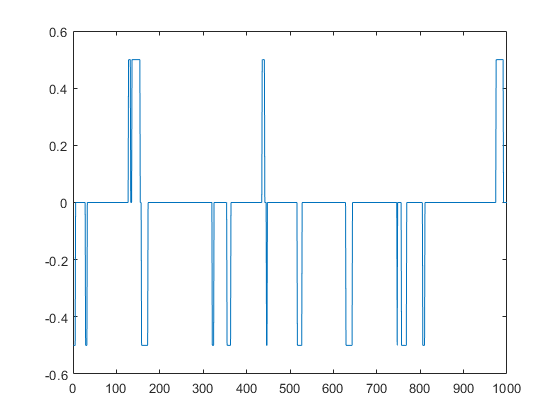

mkv_3=markov(T, mkvProcess_3.TransitionMatrix, 0, randomicVector);
plot(mkvProcess_3.StateVector(mkv_3));

Quando definimos N = 3, podemos observar que o valor do coeficiente de autorregressão de primeira ordem teórico para a cadeia de Markov é de 0,9332. Como o número de estados é N = 3, este processo não é capaz de se aproximar bem do verdadeiro valor do coeficiente de autorregressão de primeira ordem.

**(2) Next, use N = 7 and N = 15 and compare how the results differ in terms of quality of approximation.**

% Processo com N = 7
N=7;
% gerando processo de markov
mkvProcess_7 = MarkovProcess(rho,sigma,r,N,mu);
AnaliseMarkovToAr(mkvProcess_7);

______________________________________________________
                    original process     Markov chain
______________________________________________________
Persistence                 0.800000         0.798393
Standard deviation          0.166667         0.183818
______________________________________________________



mkv_7=markov(T, mkvProcess_7.TransitionMatrix, 0, randomicVector);

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

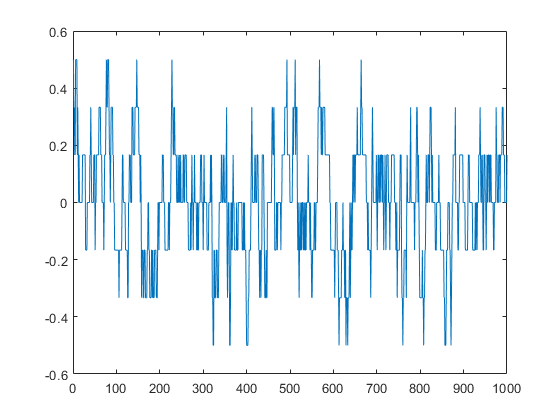


plot(mkvProcess_7.StateVector(mkv_7));


% Processo com N = 15
N=15;
% gerando processo de markov
mkvProcess_15 = MarkovProcess(rho,sigma,r,N,mu);
AnaliseMarkovToAr(mkvProcess_15);

______________________________________________________
                    original process     Markov chain
______________________________________________________
Persistence                 0.800000         0.798487
Standard deviation          0.166667         0.169273
______________________________________________________



mkv_15=markov(T, mkvProcess_15.TransitionMatrix, 0, randomicVector);

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

probability: 1.000000

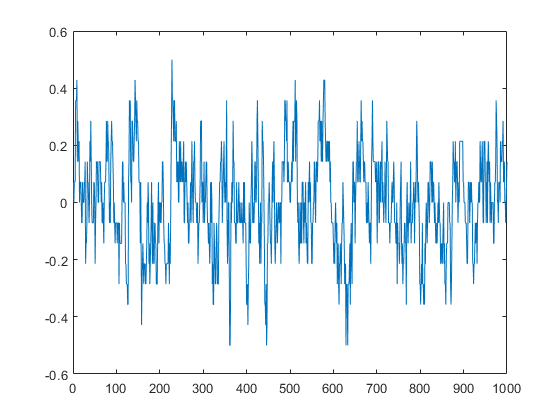


plot(mkvProcess_15.StateVector(mkv_15));

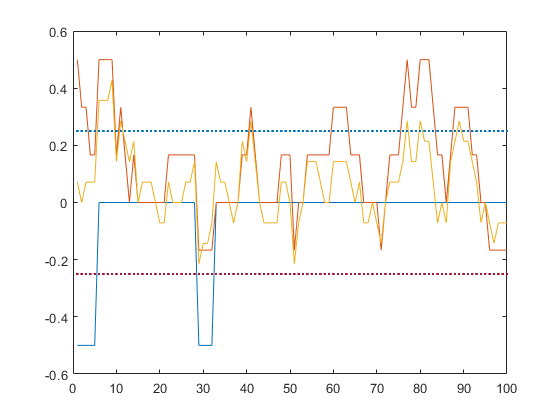


plot(1:T,   [mkvProcess_3.StateVector(mkv_3); ... 
    mkvProcess_7.StateVector(mkv_7); ... 
    mkvProcess_15.StateVector(mkv_15)], '-', ...
     1:T, repmat(mkvProcess_3.StateBorder, T), '.');
 xlim([0,100]);

O valor do coeficiente de autorregressão de ordem teórica para a cadeia de Markov é de 0.79839 para N=7 e de 0.79849 para N=15. Podemos perceber que a função se aproxima o processo AR (1) quando aumentamos o número de estados (N).

## RBC Model

Consider the following RBC model:


$$\underset{c-t, k_{t+1}, h_t}{max}\left\{ \mathbb{E} \left[\sum^\infty_{t=0}{\beta^tu(c_t,1-h_t)} \right] \right\}$$


subject to


$$c_t+k_{t+1} = z_tF(k_t,h_t) + (1-\delta)k_t \\
ln(z_{t+1}) = \rho ln(z_t) + \epsilon_{t+1} \quad \epsilon_{t+1} \sim N(0,\sigma^2)$$


The technology is given by


$$Y_t = z_tF(k_t, h_t) = z_t k^\alpha h^{1-\alpha}$$


The first and second welfare theorems hold for this economy, therefore you can solve the social planner's problem. If needed you can recover prices using marginal productivities. Assume also that:


$$u(c, 1-h) = \frac{\left(c^\gamma (1-h)^{1-\gamma} \right)^{1-\mu}}{1-\mu}$$


**(a) Write down the Social Planner's problem in recursive formulation. **

Como temos que vale o primeiro e segundo teorema do bem estar, temos que o Social Planer maximiza a utilidade sujeita as restrições dadas. Sendo assim vamos definr $V(k_t, z_t)$ como sendo:


$$V(k_t, z_t) = \underset{c_t, k_{t+1}, h_t}{ max}\left\{ \mathbb{E} \left[ \sum_{t=0}^{\infty}{\beta^t u(z_tF(k_t, h_t) +(1-\delta)k_t - k_{t+1},1-h_t)} \right] \right\}$$



$$V(k_t, z_t) = \underset{\{k_{t+1}, h_t\}_{t=0}^{\infty}}{ max}\{ u(z_tF(k_t, h_t) +(1-\delta)k_t - k_{t+1},1-h_t) + \\ \beta \mathbb{E} \left[ \sum_{t=0}^{\infty}{\beta^t u(z_tF(k_{t+1}, h_{t+1}) +(1-\delta)k_{t+1} - k_{t+2},1-h_{t+1})} \right] \}$$


Como, para $t \ge 2$,  $k_{t}$ não aparece em $u(z_tF(k_t, h_t) - k_{t+1})$podemos reescrever o problema como


$$V(k_t, z_t) = \underset{\{k_{t+1}, h_t\}_{t=0}^{\infty}}{ max}\{ u(z_tF(k_t, h_t) +(1-\delta)k_t - k_{t+1},1-h_t) + \\+ \beta \underset{\{k_{t+2}, h_{t+1}\}_{t=0}^{\infty}}{ max} \left\{ \mathbb{E} \left[ \sum_{t=0}^{\infty}{\beta^t u(z_tF(k_{t+1}, h_{t+1}) +(1-\delta)k_{t+1} - k_{t+2},1-h_{t+1})} \right] \right\} \}$$


O qual podemos reescrever como:


$$V(k_t, z_t) = \underset{k_{t+1}, h_t}{ max}\left\{u(z_tF(k_t,h_t) + (1-\delta)k_t - k_{t+1},1-h_t) +\beta \mathbb{E} \left[V(k_{t+1}, z_{t+1}) \right] \right\}

$$


Como o problema temporal é idêntico em todos os periodos, vamos denotar os periodos futuros pelo subscrito (1). Podemos então escrever o problema da seguinte forma:


$$V(k_0, z_0) = \underset{k_{1}, h_0}{ max}\left\{u(z_0F(k_0,h_0) + (1-\delta)k_0 - k_{1},1-h_0) +\beta \mathbb{E} \left[V(k_{1}, z_{1}) \right] \right\}
$$


Como temos que $h_t$ representa a quantidade de hora de trabalho e que $k_t$ o capital da economia temos de ter: $0\le k_{t+1}$ e $0 \le h_t \le 1$.


$$V(k_0, z_0) = \underset{0 \le k_{1} ; 0 \le h_0 \le 1}{ max}\left\{u(z_0F(k_0,h_0) + (1-\delta)k_0 - k_{1},1-h_0) +\beta \mathbb{E} \left[V(k_{1}, z_{1}) \right] \right\}$$


**Calibration: We need to set the value of parameters. Use **$\beta=0.987$**, **$\mu=2$**. For the production function assume that **$\alpha=1/3$**, and **$\delta=0.012$**.**

**(b) Assume that the model period is a quarter, explain the intuition behind the value of each parameter above.**

econom_param.beta=0.987;
econom_param.mu=2;
econom_param.alpha = 1/3;
econom_param.delta = 0.012;
fprintf('Taxa de desconto anual: %f', ((1/econom_param.beta)^4 - 1)*100);

Taxa de desconto anual: 5.373496

fprintf('Taxa de depreciação anual: %f', 100*((1+econom_param.delta)^4-1)); 

Taxa de depreciação anual: 4.887093

Na parte de calibração, tentamos definir os parâmetros do nosso modelo de modo que o modelo se comporte como a economia real. Nesse caso, como estamos lidando com um trimestre, o que significa que estamos simulando uma economia em que a taxa de desconto temporal anual está próxima de 5,37%  e a taxa de depreciação está próxima de 4,8871% ao ano.

Ao definir $\mu =2
$, estamos assumindo que nosso agente representativo é mais avesso ao risco quando comparado a um agente com utilidade logritima. Além disso, ao definir $\alpha = 1/3$, estamos dizendo que a participação do capital em nossa economia é metade da participação do trabalho.

**(c) For now, assume that there is no uncertainty (i.e.,**$\sigma =0$**). Derive the Euler Equation and the intra-temporal condition. Calibrate **$\gamma$** such that hours worked in the model is 1/3 of the time endowment in the steady-state, i.e., **$h=1/3$**.**

Se não temos incerteza então teremos que $z_{t+1}= z_t = 1$.


$$\text{(1)} \quad V(k_0) = \underset{0 \le k_{1} ; 0 \le h_0 \le 1}{ max}\left\{u(F(k_0,h_0) + (1-\delta)k_0 - k_{1},1-h_0) +\beta V(k_{1}) \right\}$$


Assumindo que a função valor é diferenciavel e continua, temos:


$$\text{(2)} \quad k_1: u_{(1)}(c, 1-h) [-1] + \beta V_{(1)}(k_1) =0 \\
\text{(3)} \quad h: u_{(1)}( c, 1-h) [zk^{\alpha}(1-\alpha)h^{-\alpha}] + u_{(2)}(c, 1-h) =0$$


onde 


$$c = f(k,h) +(1-\delta)k - k_1$$


Pelo teorema do envelope temos:


$$\text{(4)} \quad V_{(1)} = u_{(1)}(c, 1-h) [ \alpha k^{\alpha-1}h^{1-\alpha}+(1-\delta)]$$


logo substituindo a equação (4) em (1) temos 


$$\text{(5)} \quad u_{(1)}(c, 1-h) = \beta  u_{(1)}(c_1, 1-h_1) [ \alpha k_1^{\alpha-1}h_1^{1-\alpha}+(1-\delta)] \\
\text{(6)} \quad \frac{u_{(1)}(c, 1-h)}{\beta  u_{(1)}(c_1, 1-h_1)}= \alpha k_1^{\alpha-1}h_1^{1-\alpha}+(1-\delta)$$


Como temos:


$$\text{(7)} \quad u_{(1)}(c, 1-h) =  [c^\gamma(1-h)^{1-\gamma}]^{-\mu}\gamma (1-h_t)^{1-\gamma}c^{\gamma-1} \\
\text{(8)} \quad  u_{(2)}(c, 1-h) =  [c^\gamma(1-h)^{1-\gamma}]^{-\mu}(1-\gamma)c_t^\gamma (1-h)^{-\gamma} (-1)$$


Substituindo (7) em (6) temos:


$$\text{(9)} \quad  \left(\frac{c}{c_1}\right)^{\gamma-1-\mu\gamma} = \beta\left[z \alpha \left(\frac{h_1}{k_1}\right)^{1-\alpha}+(1-\delta) \right] \left(\frac{1+h_1}{1+h}\right)^{(1-\gamma)(1-\mu)}$$


substituindo (7) e (8) em (3) temos


$$\text{(10)} \quad  \frac{1-\gamma}{\gamma} \frac{c}{1-h} = z(1-\alpha)\left(\frac{k}{h}\right)^{-\alpha}$$


As equacoes (10) e (9) sao as equações de Euler e equação intra-temporal.

Utilizando a equação (9) podemos obter a relação entre $k_{ss}$ e $h_{ss}$ (valores de *steady state*)


$$\text{(11)} \quad 1=\beta  \left[ z \alpha \left( \frac{h_{ss}}{k_{ss}} \right)^{1-\alpha} +(1-\delta) \right]$$


% Dado do problema
h_ss = 1/3;

% Calcula os parametros de Steady State, utilizando eq (11):
[h_ss, k_ss, y_ss, c_ss] = ComputeSteadyState(h_ss, econom_param);

% Calibrando a equacao utilizando a eq (10)
f=@(gamma)(1-gamma)/(1-h_ss) - (gamma*(1-econom_param.alpha)*y_ss)/(c_ss*h_ss);
gamma = fsolve(f, 0.5);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



fprintf('h_ss=%03.4f\nk_ss=%3.4f\nc_ss=%3.4f\ny_ss=%3.4f\ngamma=%3.4f', ...
    h_ss, k_ss, c_ss, y_ss, gamma);

h_ss=0.3333
k_ss=16.0635
c_ss=1.0203
y_ss=1.2130
gamma=0.3868

% adiciona gamma aos parametros da economia
econom_param.gamma = gamma;



**Calibration (cont.): For the stochastic process, assume the values of Cooley and Prescott (1985): **$\rho = 0.95$**, and **$\sigma=0.007$

**(d) Now assume that there is uncertainty. Solve the model using the value function algorithm. Use the method of Tauchen (1986) with 7 grid points. For the capital grid you can use a linear grid with 101 points in the interval from [0:75 kss; 1:25 kss]. Report the number of value function iteration, the time it takes to find the optimal value function, plot figure of the policy function and calculate Euler Errors.**

%% SECTION I: Parameters

% Inicia o Cronometro
tic

test_param.T = 101;
test_param.epsilon = 1e-5;
test_param.mkv.rho = 0.95;
test_param.mkv.sigma = 0.007;
test_param.mkv.r = 3;
test_param.mkv.N = 7;
test_param.mkv.mu = 0;

test_param.printInterations = 25;

% Calcula os choques do estado de Mkv
mkv = MarkovProcess(test_param.mkv.rho, test_param.mkv.sigma, test_param.mkv.r, ...
    test_param.mkv.N, test_param.mkv.mu);
z.values = exp(mkv.StateVector);
z.TransitionMatrix = mkv.TransitionMatrix;

h_ss =1/3;
[h_ss, k_ss, y_ss, c_ss] = ComputeSteadyState(h_ss, econom_param);

fprintf('Time (Parameters): %.2f [secs]\n', toc);

Time (Parameters): 0.43 [secs]


%% SECTION II: Bellman Function


% Calcula a Utilidade em um "cubo" de grid de variaveis.
% (1)-axis: k1
% (2)-axis: h
% (3)-axis: k
U_1 = Utility(k_ss, econom_param, test_param, z.values(1));
U_2 = Utility(k_ss, econom_param, test_param, z.values(2));
U_3 = Utility(k_ss, econom_param, test_param, z.values(3));
U_4 = Utility(k_ss, econom_param, test_param, z.values(4));
U_5 = Utility(k_ss, econom_param, test_param, z.values(5));
U_6 = Utility(k_ss, econom_param, test_param, z.values(6));
U_7 = Utility(k_ss, econom_param, test_param, z.values(7));
fprintf('Time (Utility Determination): %.2f [secs]\n', toc);

Time (Utility Determination): 4.38 [secs]



% Inicializacao dos sete vetores da value function
V_star_1 = zeros(test_param.T, 1);
V_star_2 = zeros(test_param.T, 1);
V_star_3 = zeros(test_param.T, 1);
V_star_4 = zeros(test_param.T, 1);
V_star_5 = zeros(test_param.T, 1);
V_star_6 = zeros(test_param.T, 1);
V_star_7 = zeros(test_param.T, 1);

% Initializa a condicao de parada das interacoes (um para cada estado)
check=ones(1,test_param.mkv.N);

% Initializa o contador de interacoes
nContador=0;

% if que controla executa ou nao processo de interacao 
% apenas para questoes de debug
if 1==1

    fprintf('_______________________________________\n');
    fprintf('Interação      | Time   | eps (%f)\n', test_param.epsilon);
    fprintf('---------------------------------------\n');
    
    % inicializa os vetores de politica (k x z)
    policyIndex_h = nan(size(U_1.k_domain, 2), mkv.QtdStates);
    policyIndex_k = nan(size(U_1.h_domain, 2), mkv.QtdStates);
    
    
    while min(check) > test_param.epsilon
        % Incrementa o numero de interacoes
        nContador = nContador + 1;
        
        
        % CALCULA AS MATRIZES DE MEDIA DO TVi
        TV1_average = z.TransitionMatrix(1,1)*V_star_1 + ...
            z.TransitionMatrix(1,2)*V_star_2 + ...
            z.TransitionMatrix(1,3)*V_star_3 + ...
            z.TransitionMatrix(1,4)*V_star_4 + ...
            z.TransitionMatrix(1,5)*V_star_5 + ...
            z.TransitionMatrix(1,6)*V_star_6 + ...
            z.TransitionMatrix(1,7)*V_star_7;
        
        TV2_average = z.TransitionMatrix(2,1)*V_star_1 + ...
            z.TransitionMatrix(2,2)*V_star_2 + ...
            z.TransitionMatrix(2,3)*V_star_3 + ...
            z.TransitionMatrix(2,4)*V_star_4 + ...
            z.TransitionMatrix(2,5)*V_star_5 + ...
            z.TransitionMatrix(2,6)*V_star_6 + ...
            z.TransitionMatrix(2,7)*V_star_7;
        
        TV3_average = z.TransitionMatrix(3,1)*V_star_1 + ...
            z.TransitionMatrix(3,2)*V_star_2 + ...
            z.TransitionMatrix(3,3)*V_star_3 + ...
            z.TransitionMatrix(3,4)*V_star_4 + ...
            z.TransitionMatrix(3,5)*V_star_5 + ...
            z.TransitionMatrix(3,6)*V_star_6 + ...
            z.TransitionMatrix(3,7)*V_star_7;
        
        TV4_average = z.TransitionMatrix(4,1)*V_star_1 + ...
            z.TransitionMatrix(4,2)*V_star_2 + ...
            z.TransitionMatrix(4,3)*V_star_3 + ...
            z.TransitionMatrix(4,4)*V_star_4 + ...
            z.TransitionMatrix(4,5)*V_star_5 + ...
            z.TransitionMatrix(4,6)*V_star_6 + ...
            z.TransitionMatrix(4,7)*V_star_7;
        
        TV5_average = z.TransitionMatrix(5,1)*V_star_1 + ...
            z.TransitionMatrix(5,2)*V_star_2 + ...
            z.TransitionMatrix(5,3)*V_star_3 + ...
            z.TransitionMatrix(5,4)*V_star_4 + ...
            z.TransitionMatrix(5,5)*V_star_5 + ...
            z.TransitionMatrix(5,6)*V_star_6 + ...
            z.TransitionMatrix(5,7)*V_star_7;
        
        TV6_average = z.TransitionMatrix(6,1)*V_star_1 + ...
            z.TransitionMatrix(6,2)*V_star_2 + ...
            z.TransitionMatrix(6,3)*V_star_3 + ...
            z.TransitionMatrix(6,4)*V_star_4 + ...
            z.TransitionMatrix(6,5)*V_star_5 + ...
            z.TransitionMatrix(6,6)*V_star_6 + ...
            z.TransitionMatrix(6,7)*V_star_7;
        
        TV7_average = z.TransitionMatrix(7,1)*V_star_1 + ...
            z.TransitionMatrix(7,2)*V_star_2 + ...
            z.TransitionMatrix(7,3)*V_star_3 + ...
            z.TransitionMatrix(7,4)*V_star_4 + ...
            z.TransitionMatrix(7,5)*V_star_5 + ...
            z.TransitionMatrix(7,6)*V_star_6 + ...
            z.TransitionMatrix(7,7)*V_star_7;
        
        
        % Dimensionaliza as matrizes
        % Atencao, inverto TV1_average pois ele eh funcao de k
        V_cube_1 = repmat(TV1_average', test_param.T, 1, test_param.T);
        V_cube_2 = repmat(TV2_average', test_param.T, 1, test_param.T);
        V_cube_3 = repmat(TV3_average', test_param.T, 1, test_param.T);
        V_cube_4 = repmat(TV4_average', test_param.T, 1, test_param.T);
        V_cube_5 = repmat(TV5_average', test_param.T, 1, test_param.T);
        V_cube_6 = repmat(TV6_average', test_param.T, 1, test_param.T);
        V_cube_7 = repmat(TV7_average', test_param.T, 1, test_param.T);
        
        
        % Finds the new TV1
        [TV_1, policyIndex_h(:,1), policyIndex_k(:,1)] = TV_op(U_1.Value, ...
            econom_param, V_cube_1);
        [TV_2, policyIndex_h(:,2), policyIndex_k(:,2)] = TV_op(U_2.Value, ...
            econom_param, V_cube_2);
        [TV_3, policyIndex_h(:,3), policyIndex_k(:,3)] = TV_op(U_3.Value, ...
            econom_param, V_cube_3);
        [TV_4, policyIndex_h(:,4), policyIndex_k(:,4)] = TV_op(U_4.Value, ...
            econom_param, V_cube_4);
        [TV_5, policyIndex_h(:,5), policyIndex_k(:,5)] = TV_op(U_5.Value, ...
            econom_param, V_cube_5);
        [TV_6, policyIndex_h(:,6), policyIndex_k(:,6)] = TV_op(U_6.Value, ...
            econom_param, V_cube_6);
        [TV_7, policyIndex_h(:,7), policyIndex_k(:,7)] = TV_op(U_7.Value, ...
            econom_param, V_cube_7);
        
        % Sets the new numerical value for the stopping rule
        check(1) = norm(TV_1 - V_star_1)/norm(V_star_1);
        check(2) = norm(TV_2 - V_star_2)/norm(V_star_2);
        check(3) = norm(TV_3 - V_star_3)/norm(V_star_3);
        check(4) = norm(TV_4 - V_star_4)/norm(V_star_4);
        check(5) = norm(TV_5 - V_star_5)/norm(V_star_5);
        check(6) = norm(TV_6 - V_star_6)/norm(V_star_6);
        check(7) = norm(TV_7 - V_star_7)/norm(V_star_7);
        
        % Sets V to be the last TV we found
        V_star_1 = TV_1;
        V_star_2 = TV_2;
        V_star_3 = TV_3;
        V_star_4 = TV_4;
        V_star_5 = TV_5;
        V_star_6 = TV_6;
        V_star_7 = TV_7;
        
        if mod(nContador, test_param.printInterations ) == 0
            fprintf('  %13d| %6.2f | %12.10f\n', nContador, toc, max(check));
        end
    end
    
    fprintf('_______________________________________\n');
    fprintf('Total   %7d| %6.2f | %12.10f\n', nContador, toc, max(check));
    fprintf('---------------------------------------\n');
end

_______________________________________


Interação      | Time   | eps (0.000010)


---------------------------------------


             25|   7.70 | 0.0395297936
             50|  10.55 | 0.0155434081
             75|  13.62 | 0.0084147242
            100|  16.85 | 0.0051413079
            125|  19.86 | 0.0033391096
            150|  22.92 | 0.0022466059
            175|  26.21 | 0.0015452696
            200|  29.63 | 0.0010783307
            225|  32.94 | 0.0007598567
            250|  36.65 | 0.0005390474
            275|  39.90 | 0.0003841943
            300|  43.15 | 0.0002747283
            325|  46.41 | 0.0001969120
            350|  49.83 | 0.0001413725
            375|  53.12 | 0.0001016190
            400|  56.38 | 0.0000731063
            425|  59.63 | 0.0000526260
            450|  62.69 | 0.0000378998
            475|  65.69 | 0.0000273031
            500|  68.71 | 0.0000196736
            525|  71.87 | 0.0000141785
            550|  75.08 | 0.0000102194


_______________________________________


Total       551|  75.22 | 0.0000100864


---------------------------------------


fprintf('Time (Bellman function): %.2f [secs]\n', toc);

Time (Bellman function): 75.26 [secs]


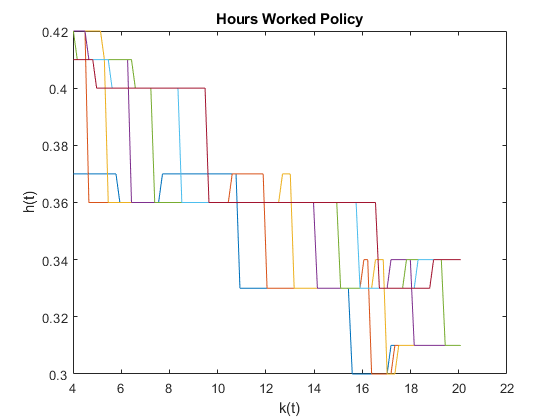


%% Determinação das policy functions

% policy_h(k_index, z_index) = h_index
% policy_k(k_index, z_index) = k_index
PolicyFunction.h_domain = U_1.h_domain;
PolicyFunction.k_domain = U_1.k_domain;

PolicyFunction.k=PolicyFunction.k_domain([1:test_param.T]'*ones(1,test_param.mkv.N));

PolicyFunction.k1 = U_1.k_domain(policyIndex_k);
PolicyFunction.h = U_1.h_domain(policyIndex_h);

PolicyFunction.y = PolicyFunction.k.^econom_param.alpha .* ...
    PolicyFunction.h.^(1-econom_param.alpha)*diag(z.values);
PolicyFunction.c = PolicyFunction.y  ...
    + (1-econom_param.delta)*PolicyFunction.k + ...
    - PolicyFunction.k1;

PolicyFunction.i = PolicyFunction.y - PolicyFunction.c;

figure
plot(PolicyFunction.k_domain, PolicyFunction.h);
xlabel('k(t)');
ylabel('h(t)');
title('Hours Worked Policy');

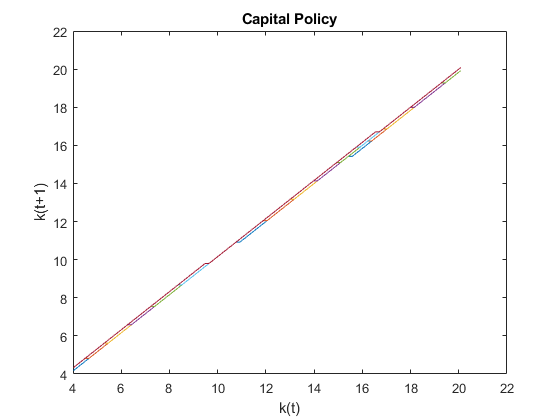


figure
plot(PolicyFunction.k_domain, PolicyFunction.k1);
xlabel('k(t)');
ylabel('k(t+1)');
title('Capital Policy');

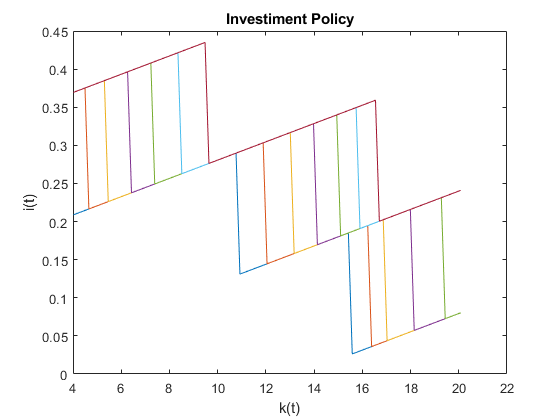


figure
plot(PolicyFunction.k_domain, PolicyFunction.i);
xlabel('k(t)');
ylabel('i(t)');
title('Investiment Policy');

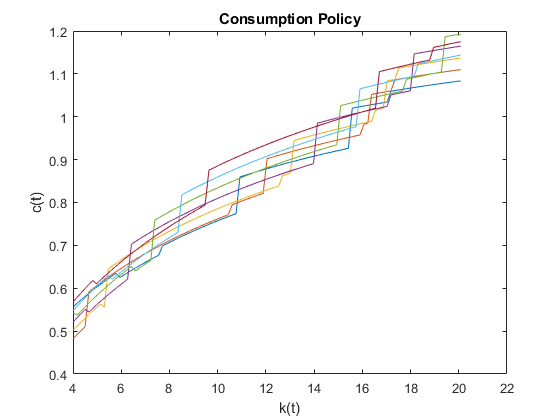


figure
plot(PolicyFunction.k_domain, PolicyFunction.c);
xlabel('k(t)');
ylabel('c(t)');
title('Consumption Policy');

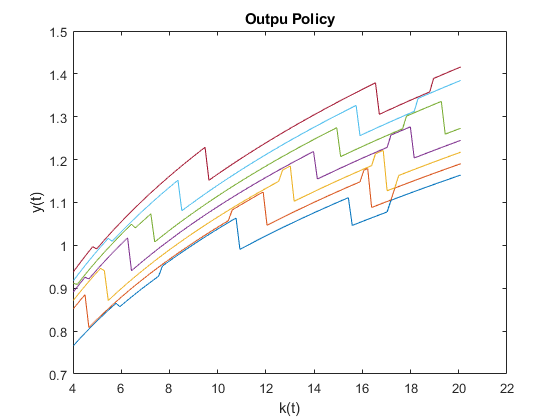


figure
plot(PolicyFunction.k_domain, PolicyFunction.y);
xlabel('k(t)');
ylabel('y(t)');
title('Outpu Policy');


fprintf('Time (Policy function plot): %.2f [secs]\n',toc);

Time (Policy function plot): 77.19 [secs]



%% CALCULO DOS ERROS DE EULER


% Funcao de retorno efetivo
% R(kt,zt) = zg(zt)*F_Prime_k(kt,ht) + 1-econom_param.delta
% R = diag(z.values)* econom_param.alpha .* k1_f^
% Define a derivada da funcao de producao com relacao a k.
Matrix_F_1=econom_param.alpha.*PolicyFunction.k.^(econom_param.alpha-1).* ...
    PolicyFunction.h.^(1-econom_param.alpha)*diag(z.values);
ER = Matrix_F_1*z.TransitionMatrix';

U_prime = (PolicyFunction.c.^econom_param.gamma .* ...
    (1.-PolicyFunction.h).^(1-econom_param.gamma)).^(-econom_param.mu) .* ...
    econom_param.gamma.*(1-PolicyFunction.h).^(1-econom_param.gamma) .* ...
    PolicyFunction.c .^(econom_param.gamma -1);
EUprime = U_prime*z.TransitionMatrix';


% Embora eu acredito que o correto deveria ser u'^-1 = pre-imagem de u'
% mas estamos usando que u'^-1 = 1/u' pois foi assim que foi feito anteriormente
Euler=log10(abs(1-(econom_param.beta.*ER.*EUprime).^(-1).*PolicyFunction.c.^(-1)));

EEE = mean(Euler);

for i=1:test_param.mkv.N
    if i==1
        fprintf('The average E.E.E. is:\n');
    end
    fprintf('Z(%d)\t%f\n',i,EEE(i));
end

The average E.E.E. is:


Z(1)	1.782130
Z(2)	1.768907
Z(3)	1.753905
Z(4)	1.738281
Z(5)	1.722935
Z(6)	1.709336
Z(7)	1.697906




%% MOMENTOS DAS VARIAVEIS

% The mean
Means = [mean(PolicyFunction.c(:)) mean(PolicyFunction.h(:)) ...
    mean(PolicyFunction.k1(:)) mean(PolicyFunction.i(:))];
Vars = [var(PolicyFunction.c(:)) var(PolicyFunction.h(:)) ...
    var(PolicyFunction.k1(:)) var(PolicyFunction.i(:))];
disp(table(categorical({'Consumption'; 'Hours worked'; 'Capital'; 'Investment'}),...
    Means',Vars', 'VariableNames',{'Variable' 'Mean' 'Variance'}));

      Variable       Mean       Variance 
    ____________    _______    __________

    Consumption     0.87161      0.031274
    Hours worked    0.35424    0.00088339
    Capital          12.151         20.83
    Investment      0.24818      0.010055



**(e) Now solve the model using Howard's improvement algorithm. Iterate 20 times in the policy function before updating your value function. Report the number of value function iteration, the time it takes to find the optimal value function,plot the figure of the policy function and calculate Euler Errors.**

%% SECTION I: Parameters

% limpeza de variaveis antigas
%clear all
clc

% Inicia o Cronometro
tic

% econom_param.beta=0.987;
% econom_param.mu=2;
% econom_param.alpha = 1/3;
% econom_param.delta = 0.012;
% econom_param.gamma = 0.386810;

% test_param.T = 101;
% test_param.epsilon = 1e-6;
% test_param.mkv.rho = 0.95;
% test_param.mkv.sigma = 0.007;
% test_param.mkv.r = 3;
% test_param.mkv.N = 7;
% test_param.mkv.mu = 0;

% Calcula os choques do estado de Mkv
mkv = MarkovProcess(test_param.mkv.rho, test_param.mkv.sigma, test_param.mkv.r, ...
    test_param.mkv.N, test_param.mkv.mu);
z.values = exp(mkv.StateVector);
z.TransitionMatrix = mkv.TransitionMatrix;

h_ss =1/3;
[h_ss, k_ss, y_ss, c_ss] = ComputeSteadyState(h_ss, econom_param);

fprintf('Time (Parameters): %.2f [secs]\n', toc);

Time (Parameters): 0.23 [secs]


%% SECTION II: Bellman Function


% Calcula a Utilidade em um "cubo" de grid de variaveis.
% (1)-axis: k1
% (2)-axis: h
% (3)-axis: k
U_1 = Utility(k_ss, econom_param, test_param, z.values(1));
U_2 = Utility(k_ss, econom_param, test_param, z.values(2));
U_3 = Utility(k_ss, econom_param, test_param, z.values(3));
U_4 = Utility(k_ss, econom_param, test_param, z.values(4));
U_5 = Utility(k_ss, econom_param, test_param, z.values(5));
U_6 = Utility(k_ss, econom_param, test_param, z.values(6));
U_7 = Utility(k_ss, econom_param, test_param, z.values(7));
fprintf('Time (Utility Determination): %.2f [secs]\n', toc);

Time (Utility Determination): 4.14 [secs]



% Inicializacao dos sete vetores da value function
V_star_1 = zeros(test_param.T, 1);
V_star_2 = zeros(test_param.T, 1);
V_star_3 = zeros(test_param.T, 1);
V_star_4 = zeros(test_param.T, 1);
V_star_5 = zeros(test_param.T, 1);
V_star_6 = zeros(test_param.T, 1);
V_star_7 = zeros(test_param.T, 1);

% Initializa a condicao de parada das interacoes (um para cada estado)
check=ones(1,test_param.mkv.N);

if 1==1
    % Initializa o contador de interacoes
    nContador=0;
    
    fprintf('_______________________________________\n');
    fprintf('Interação      | Time   | eps (%f)\n', test_param.epsilon);
    fprintf('---------------------------------------\n');
    
    % inicializa os vetores de politica (k x z)
    policyIndex_h = nan(size(U_1.k_domain, 2), mkv.QtdStates);
    policyIndex_k = nan(size(U_1.h_domain, 2), mkv.QtdStates);
    
    
    while min(check) > test_param.epsilon
        % Incrementa o numero de interacoes
        nContador = nContador + 1;
        
        
        % CALCULA AS MATRIZES DE MEDIA DO TVi
        TV1_average = z.TransitionMatrix(1,1)*V_star_1 + ...
            z.TransitionMatrix(1,2)*V_star_2 + ...
            z.TransitionMatrix(1,3)*V_star_3 + ...
            z.TransitionMatrix(1,4)*V_star_4 + ...
            z.TransitionMatrix(1,5)*V_star_5 + ...
            z.TransitionMatrix(1,6)*V_star_6 + ...
            z.TransitionMatrix(1,7)*V_star_7;
        
        TV2_average = z.TransitionMatrix(2,1)*V_star_1 + ...
            z.TransitionMatrix(2,2)*V_star_2 + ...
            z.TransitionMatrix(2,3)*V_star_3 + ...
            z.TransitionMatrix(2,4)*V_star_4 + ...
            z.TransitionMatrix(2,5)*V_star_5 + ...
            z.TransitionMatrix(2,6)*V_star_6 + ...
            z.TransitionMatrix(2,7)*V_star_7;
        
        TV3_average = z.TransitionMatrix(3,1)*V_star_1 + ...
            z.TransitionMatrix(3,2)*V_star_2 + ...
            z.TransitionMatrix(3,3)*V_star_3 + ...
            z.TransitionMatrix(3,4)*V_star_4 + ...
            z.TransitionMatrix(3,5)*V_star_5 + ...
            z.TransitionMatrix(3,6)*V_star_6 + ...
            z.TransitionMatrix(3,7)*V_star_7;
        
        TV4_average = z.TransitionMatrix(4,1)*V_star_1 + ...
            z.TransitionMatrix(4,2)*V_star_2 + ...
            z.TransitionMatrix(4,3)*V_star_3 + ...
            z.TransitionMatrix(4,4)*V_star_4 + ...
            z.TransitionMatrix(4,5)*V_star_5 + ...
            z.TransitionMatrix(4,6)*V_star_6 + ...
            z.TransitionMatrix(4,7)*V_star_7;
        
        TV5_average = z.TransitionMatrix(5,1)*V_star_1 + ...
            z.TransitionMatrix(5,2)*V_star_2 + ...
            z.TransitionMatrix(5,3)*V_star_3 + ...
            z.TransitionMatrix(5,4)*V_star_4 + ...
            z.TransitionMatrix(5,5)*V_star_5 + ...
            z.TransitionMatrix(5,6)*V_star_6 + ...
            z.TransitionMatrix(5,7)*V_star_7;
        
        TV6_average = z.TransitionMatrix(6,1)*V_star_1 + ...
            z.TransitionMatrix(6,2)*V_star_2 + ...
            z.TransitionMatrix(6,3)*V_star_3 + ...
            z.TransitionMatrix(6,4)*V_star_4 + ...
            z.TransitionMatrix(6,5)*V_star_5 + ...
            z.TransitionMatrix(6,6)*V_star_6 + ...
            z.TransitionMatrix(6,7)*V_star_7;
        
        TV7_average = z.TransitionMatrix(7,1)*V_star_1 + ...
            z.TransitionMatrix(7,2)*V_star_2 + ...
            z.TransitionMatrix(7,3)*V_star_3 + ...
            z.TransitionMatrix(7,4)*V_star_4 + ...
            z.TransitionMatrix(7,5)*V_star_5 + ...
            z.TransitionMatrix(7,6)*V_star_6 + ...
            z.TransitionMatrix(7,7)*V_star_7;
        
        
        % Dimensionaliza as matrizes
        % Atencao, inverto TV1_average pois ele eh funcao de k
        V_cube_1 = repmat(TV1_average', test_param.T, 1, test_param.T);
        V_cube_2 = repmat(TV2_average', test_param.T, 1, test_param.T);
        V_cube_3 = repmat(TV3_average', test_param.T, 1, test_param.T);
        V_cube_4 = repmat(TV4_average', test_param.T, 1, test_param.T);
        V_cube_5 = repmat(TV5_average', test_param.T, 1, test_param.T);
        V_cube_6 = repmat(TV6_average', test_param.T, 1, test_param.T);
        V_cube_7 = repmat(TV7_average', test_param.T, 1, test_param.T);
        
        
        % Finds the new TV1
        [TV_1, policyIndex_h(:,1), policyIndex_k(:,1)] = TV_op(U_1.Value, ...
            econom_param, V_cube_1);
        [TV_2, policyIndex_h(:,2), policyIndex_k(:,2)] = TV_op(U_2.Value, ...
            econom_param, V_cube_2);
        [TV_3, policyIndex_h(:,3), policyIndex_k(:,3)] = TV_op(U_3.Value, ...
            econom_param, V_cube_3);
        [TV_4, policyIndex_h(:,4), policyIndex_k(:,4)] = TV_op(U_4.Value, ...
            econom_param, V_cube_4);
        [TV_5, policyIndex_h(:,5), policyIndex_k(:,5)] = TV_op(U_5.Value, ...
            econom_param, V_cube_5);
        [TV_6, policyIndex_h(:,6), policyIndex_k(:,6)] = TV_op(U_6.Value, ...
            econom_param, V_cube_6);
        [TV_7, policyIndex_h(:,7), policyIndex_k(:,7)] = TV_op(U_7.Value, ...
            econom_param, V_cube_7);
        
        %     test_param.Howard
        if 1==1
            TVh_1 = TV_1;
            TVh_2 = TV_2;
            TVh_3 = TV_3;
            TVh_4 = TV_4;
            TVh_5 = TV_5;
            TVh_6 = TV_6;
            TVh_7 = TV_7;
            
            for i=1:20
                
                % Calcula o consumo para cada ponto do grid
                Uh.Consumption1 = Consumption(U_1.k_domain, ...
                    U_1.k_domain(policyIndex_k(:,1)), ...
                    U_1.h_domain(policyIndex_h(:,1)), econom_param, z.values(1));
                Uh.Consumption2 = Consumption(U_1.k_domain, ...
                    U_1.k_domain(policyIndex_k(:,2)), ...
                    U_1.h_domain(policyIndex_h(:,2)), econom_param, z.values(2));
                Uh.Consumption3 = Consumption(U_1.k_domain, ...
                    U_1.k_domain(policyIndex_k(:,3)), ...
                    U_1.h_domain(policyIndex_h(:,3)), econom_param, z.values(3));
                Uh.Consumption4 = Consumption(U_1.k_domain, ...
                    U_1.k_domain(policyIndex_k(:,4)), ...
                    U_1.h_domain(policyIndex_h(:,4)), econom_param, z.values(4));
                Uh.Consumption5 = Consumption(U_1.k_domain, ...
                    U_1.k_domain(policyIndex_k(:,5)), ...
                    U_1.h_domain(policyIndex_h(:,5)), econom_param, z.values(5));
                Uh.Consumption6 = Consumption(U_1.k_domain, ...
                    U_1.k_domain(policyIndex_k(:,6)), ...
                    U_1.h_domain(policyIndex_h(:,6)), econom_param, z.values(6));
                Uh.Consumption7 = Consumption(U_1.k_domain, ...
                    U_1.k_domain(policyIndex_k(:,7)), ...
                    U_1.h_domain(policyIndex_h(:,7)), econom_param, z.values(7));
                
                % caso o consumo seja negativo imponho consumo zero.
                Uh.Consumption1(Uh.Consumption1<0) = 0;
                Uh.Consumption2(Uh.Consumption2<0) = 0;
                Uh.Consumption3(Uh.Consumption3<0) = 0;
                Uh.Consumption4(Uh.Consumption4<0) = 0;
                Uh.Consumption5(Uh.Consumption5<0) = 0;
                Uh.Consumption6(Uh.Consumption6<0) = 0;
                Uh.Consumption7(Uh.Consumption7<0) = 0;
                
                g = econom_param.gamma;
                u = econom_param.mu;
                
                % Calcula a utilidade associada
                Uh.Value1 = (Uh.Consumption1.^g.* ...
                    (1- U_1.h_domain(policyIndex_h(:,1))).^(1-g)).^(1-u)/(1-u);
                Uh.Value2 = (Uh.Consumption2.^g.* ...
                    (1- U_1.h_domain(policyIndex_h(:,2))).^(1-g)).^(1-u)/(1-u);
                Uh.Value3 = (Uh.Consumption3.^g.* ...
                    (1- U_1.h_domain(policyIndex_h(:,3))).^(1-g)).^(1-u)/(1-u);
                Uh.Value4 = (Uh.Consumption4.^g.* ...
                    (1- U_1.h_domain(policyIndex_h(:,4))).^(1-g)).^(1-u)/(1-u);
                Uh.Value5 = (Uh.Consumption5.^g.* ...
                    (1- U_1.h_domain(policyIndex_h(:,5))).^(1-g)).^(1-u)/(1-u);
                Uh.Value6 = (Uh.Consumption6.^g.* ...
                    (1- U_1.h_domain(policyIndex_h(:,6))).^(1-g)).^(1-u)/(1-u);
                Uh.Value7 = (Uh.Consumption7.^g.* ...
                    (1- U_1.h_domain(policyIndex_h(:,7))).^(1-g)).^(1-u)/(1-u);
                
                TVh_1 = Uh.Value1' + econom_param.beta .* TVh_1(policyIndex_k(:,1));
                TVh_2 = Uh.Value2' + econom_param.beta .* TVh_2(policyIndex_k(:,2));
                TVh_3 = Uh.Value3' + econom_param.beta .* TVh_3(policyIndex_k(:,3));
                TVh_4 = Uh.Value4' + econom_param.beta .* TVh_4(policyIndex_k(:,4));
                TVh_5 = Uh.Value5' + econom_param.beta .* TVh_5(policyIndex_k(:,5));
                TVh_6 = Uh.Value6' + econom_param.beta .* TVh_6(policyIndex_k(:,6));
                TVh_7 = Uh.Value7' + econom_param.beta .* TVh_7(policyIndex_k(:,7));
            end
            % Sets the new numerical value for the stopping rule
            check(1) = norm(TVh_1 - V_star_1)/norm(V_star_1);
            check(2) = norm(TVh_2 - V_star_2)/norm(V_star_2);
            check(3) = norm(TVh_3 - V_star_3)/norm(V_star_3);
            check(4) = norm(TVh_4 - V_star_4)/norm(V_star_4);
            check(5) = norm(TVh_5 - V_star_5)/norm(V_star_5);
            check(6) = norm(TVh_6 - V_star_6)/norm(V_star_6);
            check(7) = norm(TVh_7 - V_star_7)/norm(V_star_7);
            
            fprintf('  %13d| %6.2f | %12.10f\n', nContador, toc, min(check));
            if  min(check) < test_param.epsilon
                break;
            end
            
            TV_1 = TVh_1;
            TV_2 = TVh_2;
            TV_3 = TVh_3;
            TV_4 = TVh_4;
            TV_5 = TVh_5;
            TV_6 = TVh_6;
            TV_7 = TVh_7;
            
        end
        
        % Sets the new numerical value for the stopping rule
        check(1) = norm(TV_1 - V_star_1)/norm(V_star_1);
        check(2) = norm(TV_2 - V_star_2)/norm(V_star_2);
        check(3) = norm(TV_3 - V_star_3)/norm(V_star_3);
        check(4) = norm(TV_4 - V_star_4)/norm(V_star_4);
        check(5) = norm(TV_5 - V_star_5)/norm(V_star_5);
        check(6) = norm(TV_6 - V_star_6)/norm(V_star_6);
        check(7) = norm(TV_7 - V_star_7)/norm(V_star_7);
        
        % Sets V to be the last TV we found
        V_star_1 = TV_1;
        V_star_2 = TV_2;
        V_star_3 = TV_3;
        V_star_4 = TV_4;
        V_star_5 = TV_5;
        V_star_6 = TV_6;
        V_star_7 = TV_7;
        
        if mod(nContador, test_param.printInterations) == 0
            fprintf('  %13d| %6.2f | %12.10f\n', nContador, toc, min(check));
        elseif nContador > 1000
            error('Howard''s Method failed to converge')
        end
    end
    
    fprintf('_______________________________________\n');
    fprintf('Total   %7d| %6.2f | %12.10f\n', nContador, toc, max(check));
    fprintf('---------------------------------------\n');
end

_______________________________________


Interação      | Time   | eps (0.000010)


---------------------------------------


              1|   4.70 |          Inf
              2|   4.86 | 0.7214051049
              3|   5.01 | 0.3086789584
              4|   5.16 | 0.1725956513
              5|   5.37 | 0.1116558288
              6|   5.52 | 0.0747478370
              7|   5.65 | 0.0522624688
              8|   5.81 | 0.0376566232
              9|   5.96 | 0.0274974251
             10|   6.10 | 0.0203048979
             11|   6.25 | 0.0151184672
             12|   6.38 | 0.0113143866
             13|   6.53 | 0.0085019621
             14|   6.68 | 0.0064202843
             15|   6.82 | 0.0048399540
             16|   6.96 | 0.0036722815
             17|   7.11 | 0.0027797183
             18|   7.26 | 0.0021025910
             19|   7.40 | 0.0015920911
             20|   7.57 | 0.0012010941
             21|   7.70 | 0.0009129518
             22|   7.85 | 0.0006879340
             23|   8.00 | 0.0005231478
             24|   8.14 | 0.0003945303
             25|   8.29 | 0.0002993617


             25|   8.29 | 0.0002993617


             26|   8.44 | 0.0002277662
             27|   8.58 | 0.0001710542
             28|   8.74 | 0.0001311828
             29|   8.91 | 0.0000979792
             30|   9.06 | 0.0000750299
             31|   9.22 | 0.0000573051
             32|   9.38 | 0.0000429271
             33|   9.53 | 0.0000331018
             34|   9.69 | 0.0000248109
             35|   9.85 | 0.0000190758
             36|  10.00 | 0.0000156124
             37|  10.17 | 0.0000114405
             38|  10.33 | 0.0000079634


_______________________________________


Total        38|  10.33 | 0.0000548682


---------------------------------------


fprintf('Time (Bellman + Howard''s function): %.2f [secs]\n', toc);

Time (Bellman + Howard's function): 10.37 [secs]


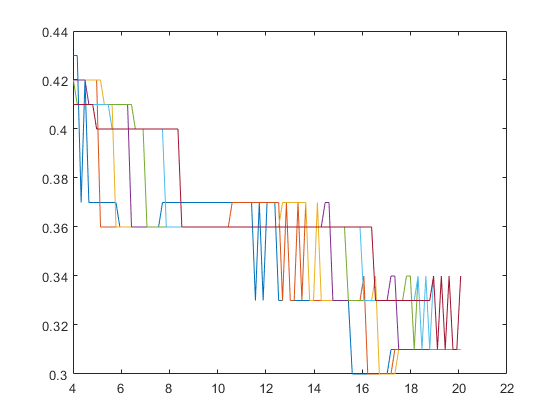


%% Determinação das policy functions

% policy_h(k_index, z_index) = h_index
% policy_k(k_index, z_index) = k_index
PolicyFunction.h_domain = U_1.h_domain;
PolicyFunction.k_domain = U_1.k_domain;

PolicyFunction.k = PolicyFunction.k_domain([1:test_param.T]'*ones(1,test_param.mkv.N));

PolicyFunction.k1 = U_1.k_domain(policyIndex_k);
PolicyFunction.h = U_1.h_domain(policyIndex_h);

PolicyFunction.y = PolicyFunction.k.^econom_param.alpha .* ...
    PolicyFunction.h.^(1-econom_param.alpha)*diag(z.values);
PolicyFunction.c = PolicyFunction.y  ...
    + (1-econom_param.delta)*PolicyFunction.k + ...
    - PolicyFunction.k1;

PolicyFunction.i = PolicyFunction.y - PolicyFunction.c;

figure
plot(PolicyFunction.k_domain, PolicyFunction.h);

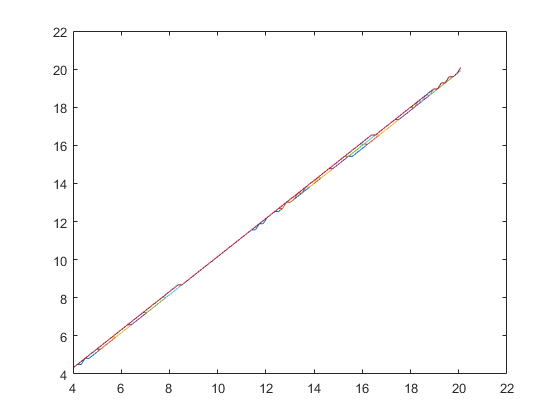


figure
plot(PolicyFunction.k_domain, PolicyFunction.k1);

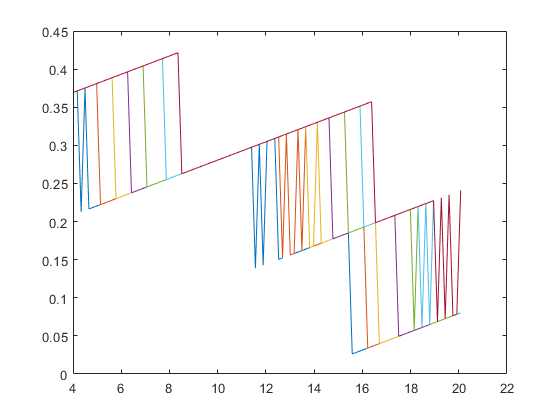


figure
plot(PolicyFunction.k_domain, PolicyFunction.i);

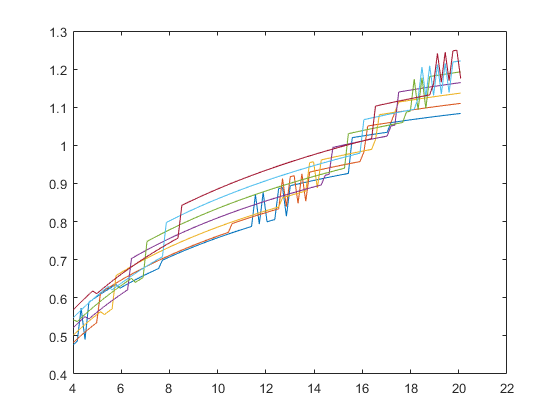


figure
plot(PolicyFunction.k_domain, PolicyFunction.c);

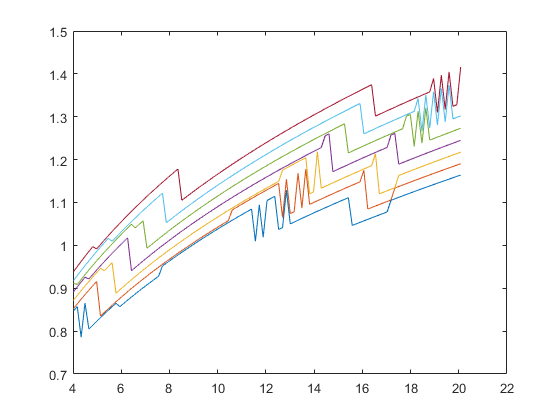


figure
plot(PolicyFunction.k_domain, PolicyFunction.y);

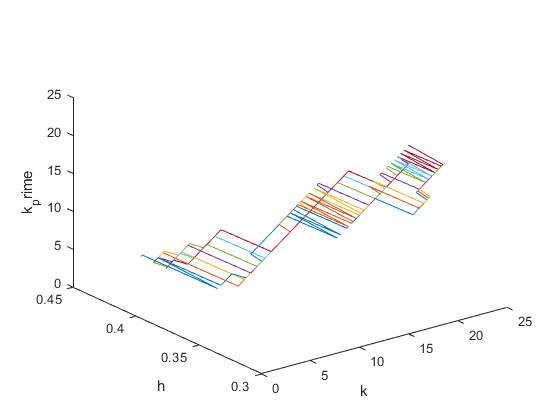


figure
plot3(U_1.k_domain(policyIndex_k), U_1.h_domain(policyIndex_h), U_1.k_domain);
xlabel('k')
ylabel('h')
zlabel('k_prime')

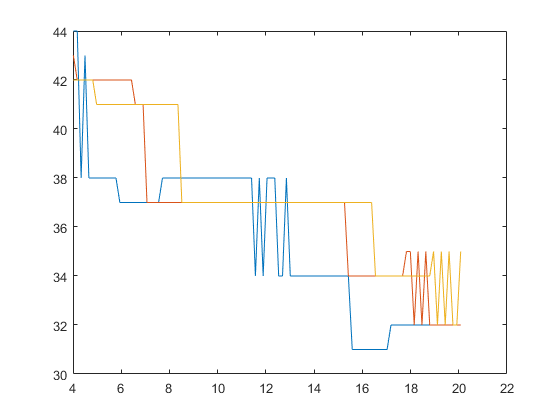


plot( U_1.k_domain, policyIndex_h(:,[1 5 7]))


fprintf('Time (Policy function plot): %.2f [secs]\n',toc);

Time (Policy function plot): 12.33 [secs]



%% CALCULO DOS ERROS DE EULER


% Funcao de retorno efetivo
% R(kt,zt) = zg(zt)*F_Prime_k(kt,ht) + 1-econom_param.delta
% R = diag(z.values)* econom_param.alpha .* k1_f^
% Define a derivada da funcao de producao com relacao a k.
Matrix_F_1=econom_param.alpha.*PolicyFunction.k.^(econom_param.alpha-1).*PolicyFunction.h.^(1-econom_param.alpha)*diag(z.values);
ER = Matrix_F_1*z.TransitionMatrix';

U_prime = (PolicyFunction.c.^econom_param.gamma .* (1.-PolicyFunction.h).^(1-econom_param.gamma)).^(-econom_param.mu).*econom_param.gamma.*(1-PolicyFunction.h).^(1-econom_param.gamma).*PolicyFunction.c .^(econom_param.gamma -1);
EUprime = U_prime*z.TransitionMatrix';


Euler = log10(abs(1-(econom_param.beta.*ER.*EUprime).^(-1).*PolicyFunction.c.^(-1)));

EEE = mean(Euler);
fprintf('The average E.E.E. is:\n');

The average E.E.E. is:


for i=1:test_param.mkv.N
    fprintf('Z(%d)\t%f\n',i,EEE(i));
end

Z(1)	1.773834
Z(2)	1.762575
Z(3)	1.750573
Z(4)	1.738078
Z(5)	1.726042
Z(6)	1.714703
Z(7)	1.704649


**(f) Calculate and report the first and second moments of consumption, hours worked, capital, investment and output.**

Feito juntamente com o item (d) e (e)